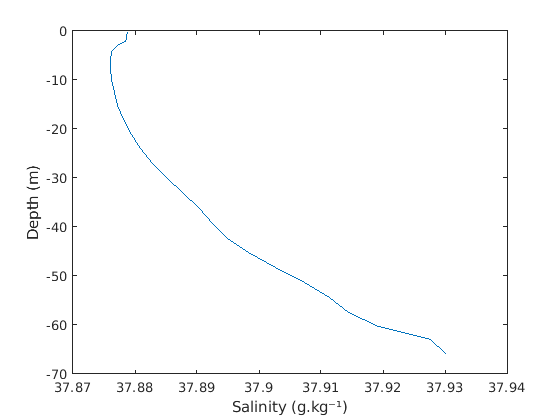

Wind = 10;
date = datetime(1999,12,19);

[KZ,Row,~,z_,Sal,Temp,Uz,Vz] = KsSalTemp2020(Wind, date);

plot(Sal,z_)
xlabel("Salinity (g.kg⁻¹)")
ylabel("Depth (m)")

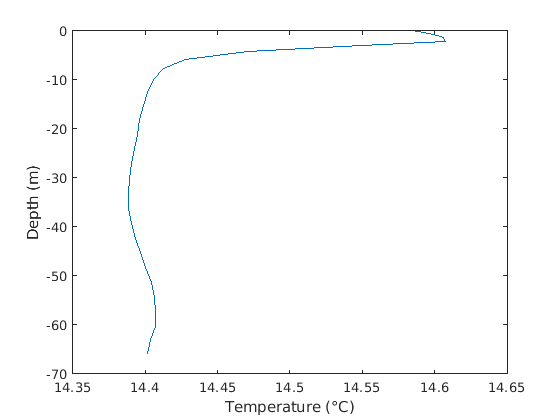

plot(Temp,z_)
xlabel("Temperature (°C)")
ylabel("Depth (m)")


Temp = Temp + 273.15; % °C -> K

Coagulation equation (Burd 2009) :


$$
{\frac{dn(m, t)}{
dt}\,}={\,\frac{\alpha}{2}\int_{0}^{m}
\beta (m_{j}, m-m_{j})n(m-m_{j}, t)n(m_{j}, t) dm_{j}}\\
{\,}{-\alpha n\left(m,t\right)\int_{0}^{\infty}\beta \left(m,m_{j}\right)n\left(m_{j},t\right)dm_{j}}\\
{\,}{-n\left(m,t\right)\frac{w_{s}\left(m\right)}{Z}+I\left(m,t\right)}\\$$


- ${\,\frac{\alpha}{2}\int_{0}^{m}
\beta (m_{j}, m-m_{j})n(m-m_{j}, t)n(m_{j}, t) dm_{j}}$ : collisions that add material in the size range $m$ to $m+dm$

- ${\,}{-\alpha n\left(m,t\right)\int_{0}^{\infty}\beta \left(m,m_{j}\right)n\left(m_{j},t\right)dm_{j}}$ : collisions that removes material in the size range $m$ to $m+dm$

- ${-n\left(m,t\right)\frac{w_{s}\left(m\right)}{Z}$ : loss rate due to sedimentation

- $I(m,t)$ : input rate of new material

### Coagulation kernel $\beta$ (McCave 1984)

Contains info on the mechanism that bring particles together. 

- Brownian motion

- Laminar shear

- Turbulent shear

- Differential sedimentation

d1 = 100e-6;
d2 = 500e-6;
d12 = d1 + d2;

#### Brownian motion

$\beta_{Br}(i,j)=2\pi D_{ij}d_{ij}=\frac{2}{3}\frac{kT}{\mu}\frac{d_{ij}^2}{d_id_j}$  with dimension $L^3T^{-1}$ ($m^3s^{-1}$)

$D_{ij} = D_i + D_j$ with $D_x=\frac{kT}{3\pi\mu d_x}$ the diffusion coefficients ($L^2T^{-1}$)

$k$ : Boltzmann constant $k= 1.38064852 \times  10^{-23} m^2.kg.s^{-2}.K^{-1}$

$T$ : absolute temperature of the water

$\mu$ : dynamic viscosity

$d_i, d_j$ : particle diameter


$$d_{ij} = d_i+d_j$$


unDynamic viscosity computation (Huber2009)

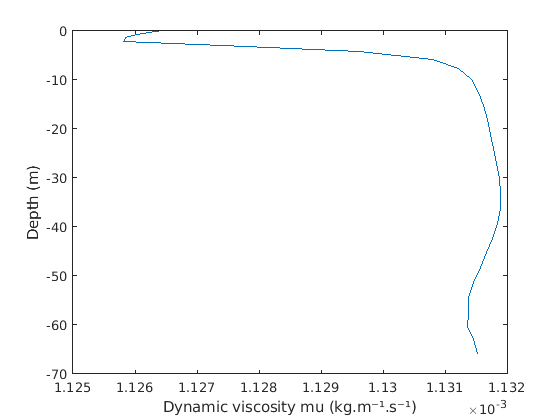

mustart = 1e-6; % kg.m⁻¹.s⁻¹
Tstart = 647.096; % K
rhostar = 322.0; % kg.m⁻³

Hi = [1.67752 2.20462 0.6366564 -0.241605]';
Hij = [5.20094e-1 2.22531e-1 -2.81378e-1 1.61913e-1 -3.25372e-2 0 0;
    8.50895e-2 9.99115e-1 -9.06851e-1 2.57399e-1 0 0 0;
    -1.08374 1.88797 -7.72479e-1 0 0 0 0;
    -2.89555e-1 1.26613 -4.89837e-1 0 6.98452e-2 0 -4.35673e-3;
    0 0 -2.57040e-1 0 0 8.72102e-3 0;
    0 1.20573e-1 0 0 0 0 -5.93264e-4];

Tbar = Temp/Tstart; % adimentional temp (K)
rhobar = Row/rhostar;

EPS0 = 0;
for i = 1:length(Hi)
    EPS0 = EPS0+Hi(i)./Tbar.^(i-1);
end, clear i,

mu0bar = 100*sqrt(Tbar)./EPS0;
clear EPS0 Hi,

EPS1i = 0;
for i = 0:5
    EPS1j = 0;
    for j = 0:6
        EPS1j = EPS1j + Hij(i+1,j+1).*(rhobar-1).^j;
    end, clear j,
    EPS1i = EPS1i + (1./Tbar-1).^i.*EPS1j;
end, clear i,
mu1bar = exp(rhobar.*EPS1i);
clear EPS1i EPS1j Hij,

mubar = mu0bar.*mu1bar;
mu = mubar.*mustart;

plot(mu,z_)
xlabel("Dynamic viscosity mu (kg.m⁻¹.s⁻¹)")
ylabel("Depth (m)")

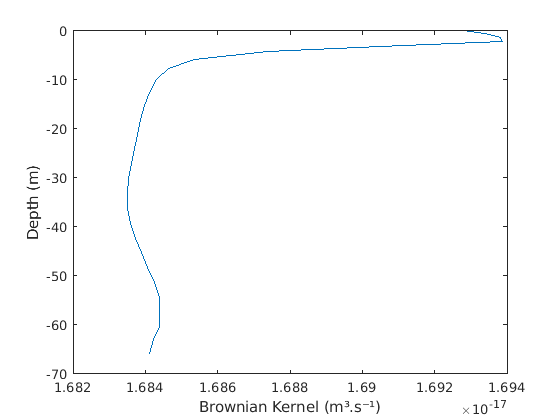

k = 1.38064852e-23;
D1 = k*Temp./(3*pi*mu*d1);
D2 = k*Temp./(3*pi*mu*d2);
D12 = D1 + D2;

Kbr = 2*pi*D12*d12;

plot(Kbr,z_)
xlabel("Brownian Kernel (m³.s⁻¹)")
ylabel("Depth (m)")

$\rightarrow$ à ajouter à la diffusion turbulente ?

clear k mu mu0 mu0bar mu1bar mubar mustart rhobar rhostar Tbar Tstart,

#### Laminar and turbulent shear

$\beta_{LS}(i,j) = \Gamma\frac{d_{ij}^3}{6}$  kernel for laminar shear with $\Gamma = \frac{dU}{dz}$

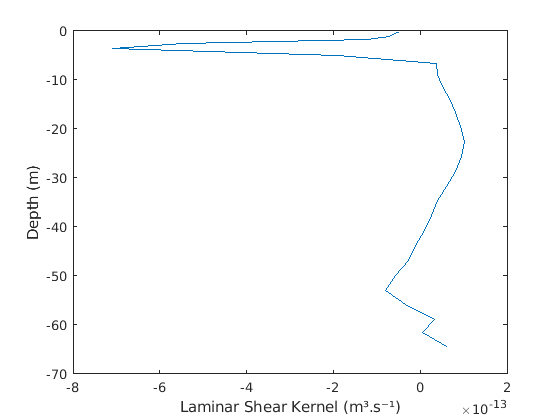

Gamma = (diff(Uz) + diff(Vz))./diff(z_); % s⁻¹
Kls = Gamma .* d12^3./6;
z__ = (z_(1:end-1)+z_(2:end))/2;

plot(Kls,z__)
xlabel("Laminar Shear Kernel (m³.s⁻¹)")
ylabel("Depth (m)")

$\beta_{TS}(i,j) = 0.163d_{ij}^3\sqrt{\frac{\epsilon}{\nu}}$  kernel for turbulent shear with $\epsilon$ the turbulent dissipation rate and $\nu$ the kinematic viscosity

$\epsilon$ ??

Simulation Param

dt_test = 60*60*2;
date = datetime(2020,03,18);
tf = 60*60*24*3;

%% Water column parameters
%% Load hydrodinamic model data
ModeleHydro='2012RHOMA_arome_003.nc';
SauvegardeModeleHydro=['DonneeBase' ModeleHydro(1:end-3)];
load(SauvegardeModeleHydro, 'H0')

%% Water column parameters
% Find depth of the column
Station = 'RN2';
% Load file with indexes corresponding to each stations
stationFile = '../Data/stationIJ_CEREGE.mat';
load(stationFile,'stationIJ');
% Get the indexes of the right station
I0 = stationIJ{stationIJ{:,'station'} == Station,'I0'};
J0 = stationIJ{stationIJ{:,'station'} == Station,'J0'};
L = H0(I0,J0); % depth
clear H0 stationIJ,

N = 50;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 100;
pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
sizeMP = random(pd,nMP,1);
sizeMP(sizeMP<1e-6) = 1e-6;
clear pd,
% zInit = linspace(0,L,nPart);
zInitMP = linspace(0,L,nMP);
frag = 0;

wind = 100;
rhoMP = 1000;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

% create list of particles
mp = getMPlist(nMP, sizeMP, rhoMP, rhow, frag);

Launch simulation

% [zFinal, dt, mpFinal] = MP_simulatorAgg(mp, zInit, K, dK, L, dz, tf, dt_test, 0);

#### Simulation parameters for two types of particles : MP and OrgaAggr

dt_test = 60*60*2;
date = datetime(2020,03,18);
tf = 60*60*24*3;

%% Water column parameters
%% Load hydrodinamic model data
ModeleHydro='2012RHOMA_arome_003.nc';
SauvegardeModeleHydro=['DonneeBase' ModeleHydro(1:end-3)];
load(SauvegardeModeleHydro, 'H0')

%% Water column parameters
% Find depth of the column
Station = 'RN2';
% Load file with indexes corresponding to each stations
stationFile = '../Data/stationIJ_CEREGE.mat';
load(stationFile,'stationIJ');
% Get the indexes of the right station
I0 = stationIJ{stationIJ{:,'station'} == Station,'I0'};
J0 = stationIJ{stationIJ{:,'station'} == Station,'J0'};
L = H0(I0,J0); % depth
clear H0 stationIJ,

N = 50;
dz= L/N;  z=0:dz:L; % z : boundaries of the meshes
z_=(z(1:end-1)+z(2:end))/2; % middle of each mesh  

nMP = 100;
pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
sizeMP = random(pd,nMP,1);
sizeMP(sizeMP<1e-6) = 1e-6;
clear pd,
zInitMP = linspace(0,L,nMP);
rhoMP = 1000;

nAgg = 100;
pd = makedist('Normal', 'mu', 450e-6, 'sigma', 50e-6);
sizeAgg = random(pd,nMP,1);
sizeAgg(sizeAgg<1e-6) = 1e-6;
clear pd,
zInitAgg = linspace(0,L,nAgg);
rhoAgg = 1030;

wind = 10;

[KZ_day,Row_day,z_day,z__day] = KsSalTemp2020(wind, date);
[K,dK] = Diffusivity(z,z_,dz,0.8,0,KZ_day,z_day');
rhow = interp1(-z__day,Row_day,z,'pchip'); % density of sea water 
clear KZ_day Row_day z_day z__day,

%% create list of MP
% allocate memory to store particles
mp_list(nMP) = MP; % array of MP objects
% Fill the array
for i = 1:(nMP)
    mp_list(i) = MP(sizeMP(i), rhoMP, rhow, i);
end, clear i,

%% create list of Agrr
% allocate memory to store particles
agg_list(nAgg) = Aggr; % array of Aggr objects
% Fill the array
for i = 1:(nAgg)
    agg_list(i) = Aggr(sizeAgg(i), rhoAgg, rhow, i, 0);
end, clear i,

Burd, A. B., & Jackson, G. A. (2009). Particle aggregation. In *Annual Review of Marine Science* (Vol. 1, pp. 65–90). Annual Reviews Inc. [https://doi.org/10.1146/annurev.marine.010908.163904](https://doi.org/10.1146/annurev.marine.010908.163904)

Huber, M. L., Perkins, R. A., Laesecke, A., Friend, D. G., Sengers, J. V., Assael, M. J., Metaxa, I. N., Vogel, E., Mareš, R., & Miyagawa, K. (2009). New international formulation for the viscosity of H2O. *Journal of Physical and Chemical Reference Data*, *38*(2), 101–125. [https://doi.org/10.1063/1.3088050](https://doi.org/10.1063/1.3088050)

McCave, I. N. (1984). Size spectra and aggregation of suspended particles in the deep ocean. *Deep Sea Research Part A, Oceanographic Research Papers*, *31*(4), 329–352. [https://doi.org/10.1016/0198-0149(84)90088-8](https://doi.org/10.1016/0198-0149(84)90088-8)